K = 2; % number of clusters (number of Gaussians)
D = 2; % number of dimensions in each Gaussian

mu1 = [3, 4];
mu2 = [9, 8];

sigma1 = [1, 0.5; 0.5, 1];
sigma2 = [1, -0.2; -0.2, 1];

phi = [0.3, 0.7];
N = 1000;

## Step 1: generate sample from the mixture of two bivariate Gaussians

rng('default') % reproducible

X = sampleGaussianMixture(N, {mu1, mu2}, {sigma1, sigma2}, phi);

## Step 2: implement the EM algorithm and get some results

[MU, SIGMA, PI] = my_em(X, phi, K);

Num iterations in EM algo: 2 


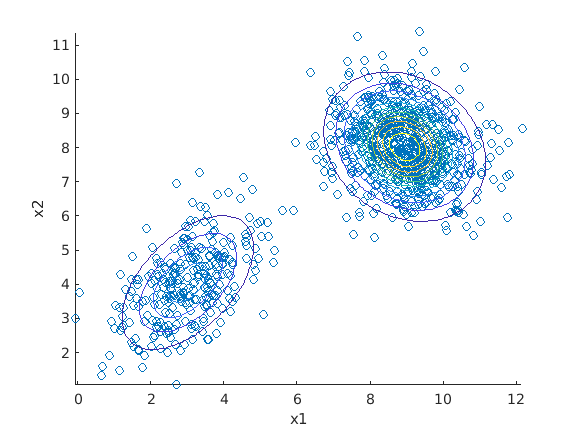


% Plotting the resulting mixture of gaussians: 

% Probability density of mixture using the given parameters: 
%p_initial = @(x) phi(1) * mvnpdf(x, mu1, sigma1) + phi(2) * mvnpdf(x, mu2, sigma2) ;

% PDF of mixture using the parameters estimated by the EM algorithm.  
p_new = @(x) PI(1) * mvnpdf(x, MU(1,:), SIGMA{1}) + PI(2) * mvnpdf(x, MU(2,:), SIGMA{2}) ;


% Plotting the sampled data
figure(1); clf; 
X1 = X(:, 1);
X2 = X(:, 2);
scatter(X1, X2) % the two dimensions sampled from data

hold on; 

% Deterministic part: using contour to plot the mixture of gaussians
% making the grid of values
x1 = linspace(min(X1), max(X1));     % 1 x 100
x2 = linspace(min(X2), max(X2));     % 1 x 100

% joining xx2 on the right of xx1
[xx1 xx2] = meshgrid(x1, x2);        % xx1 is 100 x 100

% get the values from the multivariate pdf using the meshgrid
f = p_new([xx1(:), xx2(:)]);

% contour plot 
% note: must reshape f to be 100x100 since both the  xx1 and xx2 are 100 x 100. 
contour(xx1, xx2, reshape(f, 100, 100))
xlabel('x1') % dimension 1
ylabel('x2') % dimension 2



% Showing the results in a table
% Means comparison
meanTable = table(mu1', MU(1,:)', mu2', MU(2,:)', 'VariableNames', {'GivenMu1', 'EstMu1', 'GivenMu2', 'EstMu2'})

meanTable = 2×4 table
    GivenMu1         EstMu1         GivenMu2         EstMu2     
    ________    ________________    ________    ________________

    3           3.01497012150705    9           8.94951378554843
    4           4.04807921348503    8           8.02446374233351



% Sigma comparison
sigma1Table = table(sigma1, SIGMA{1}, 'VariableNames', {'GivenSigma1', 'EstSigma1'})

sigma1Table = 2×2 table
    GivenSigma1                  EstSigma1               
    ___________    ______________________________________

      1    0.5       1.0631315291412    0.616813729204621
    0.5      1     0.616813729204621     1.26494570117119



sigma2Table = table(sigma2, SIGMA{2}, 'VariableNames', {'GivenSigma2', 'EstSigma2'})

sigma2Table = 2×2 table
    GivenSigma2                   EstSigma2               
    ____________    ______________________________________

       1    -0.2    0.989165413178025    -0.19991777511479
    -0.2       1    -0.19991777511479     0.96196353281825



 % Prior mixture probabilities comparison
phiTable= table(phi', PI', 'VariableNames', {'GivenPrior', 'EstPrior'})

phiTable = 2×2 table
    GivenPrior        EstPrior     
    __________    _________________

    0.3            0.28104507414632
    0.7           0.718954925853679


## Doing the EM algorithm steps from the start for B = 100 iterations

B = 100;
[avgMU, avgSIGMA, avgPI, allMUs, allSIGMAs, allPIs] = averageEMResults(B, {mu1, mu2}, {sigma1, sigma2}, N, phi);

Num iterations in EM algo: 2 
Num iterations in EM algo: 2 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 2 
Num iterations in EM algo: 3 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 1 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 3 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 3 
Num iterations in EM algo: 3 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 2 
Num iterations in EM algo: 2 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 3 
Num iterat

% Showing that results are consistent (but some outpus are switched around)
disp("Means")

Means


allMUs{1:5}

ans =    3.014970121507047   4.048079213485029
   8.949513785548428   8.024463742333506


ans =    3.028297603803640   4.068528085035234
   9.023482596384765   7.973127067553421


ans =    9.037304246943526   7.982286710418736
   2.963587124753877   4.015433328274951


ans =    9.006560798481825   8.006956530305047
   2.997943442919516   4.050676091579517


ans =    2.941051381807378   3.984328624046275
   8.985446968572919   7.980526462074009


disp('First Cluster Covariance Matrices')

First Cluster Covariance Matrices


for i = 1:5
    fprintf('i = %d\n', i)
    allSIGMAs{i}{1}
end

i = 1


ans =    1.063131529141200   0.616813729204621
   0.616813729204621   1.264945701171188


i = 2


ans =    0.937611302334997   0.509824644477301
   0.509824644477301   1.015016815308992


i = 3


ans =    0.946569804681392  -0.143848171803073
  -0.143848171803073   0.960517788020688


i = 4


ans =    0.854912935122141  -0.101034305135806
  -0.101034305135806   1.036175720495212


i = 5


ans =    1.019488528402269   0.474903029980685
   0.474903029980685   1.003940550903646



disp('Second Cluster Covariance Matrices')

Second Cluster Covariance Matrices


for i = 1:5
    fprintf('i = %d\n', i)
    allSIGMAs{i}{2}
end

i = 1


ans =    0.989165413178025  -0.199917775114790
  -0.199917775114790   0.961963532818250


i = 2


ans =    1.023736099227022  -0.182977315725922
  -0.182977315725922   0.963945572977407


i = 3


ans =    0.991115984848780   0.510535016153830
   0.510535016153830   0.966388078541460


i = 4


ans =    0.917070024805630   0.526732902368317
   0.526732902368317   1.018967754271872


i = 5


ans =    0.986593905220602  -0.185884890756101
  -0.185884890756101   0.910478562798044


disp("Mixture Probabilities")

Mixture Probabilities


allPIs{1:5}

ans =    0.281045074146320   0.718954925853679


ans =    0.308595764216066   0.691404235783934


ans =    0.661710820647655   0.338289179352344


ans =    0.707838967219321   0.292161032780679


ans =    0.298019771733718   0.701980228266282



% Compare original vs estimated parameters in a table

% Means comparison
avgMeansTable = table(mu1', avgMU(1,:)', mu2', avgMU(2,:)', 'VariableNames', {'GivenMu1', 'EstMu1', 'GivenMu2', 'EstMu2'})

avgMeansTable = 2×4 table
    GivenMu1         EstMu1         GivenMu2        EstMu2     
    ________    ________________    ________    _______________

    3           6.60264787024625    9           5.3958211499299
    4           6.40309058748796    8           5.6024047116782




% Sigma comparison
avgSigma1Table = table(sigma1, avgSIGMA{1}, 'VariableNames', {'GivenSigma1', 'EstSigma1'})

avgSigma1Table = 2×2 table
    GivenSigma1                   EstSigma1                
    ___________    ________________________________________

      1    0.5      0.997236501620181    0.0732853396840627
    0.5      1     0.0732853396840627     0.998108865814018



avgSigma12able = table(sigma2, avgSIGMA{2}, 'VariableNames', {'GivenSigma2', 'EstSigma2'})

avgSigma12able = 2×2 table
    GivenSigma2                   EstSigma2               
    ____________    ______________________________________

       1    -0.2    0.984961790229438    0.218806765812918
    -0.2       1    0.218806765812918    0.990363715056687



 % Prior mixture probabilities comparison
 avgPiTable = table(phi', avgPI', 'VariableNames', {'GivenPrior', 'EstPrior'})

avgPiTable = 2×2 table
    GivenPrior        EstPrior     
    __________    _________________

    0.3           0.540908968780276
    0.7           0.459091031219724
